# **静电型幻觉装置演示**

**        与静电隐身的分析类似，假设有一双层柱状结构，中心圆柱由完美金属构成，即介电常数**$\varepsilon_1$**为无穷大，任何电场都进入不到柱体内部。金属材料外部是一个内外半径分别为a和b的柱套，其介电常数为**$\varepsilon_2$**。当在背景材料中施加一个垂直于柱轴方向的匀强电场时，该电场产生的扰动与半径为b的由不同材料组成的介质柱相同。**

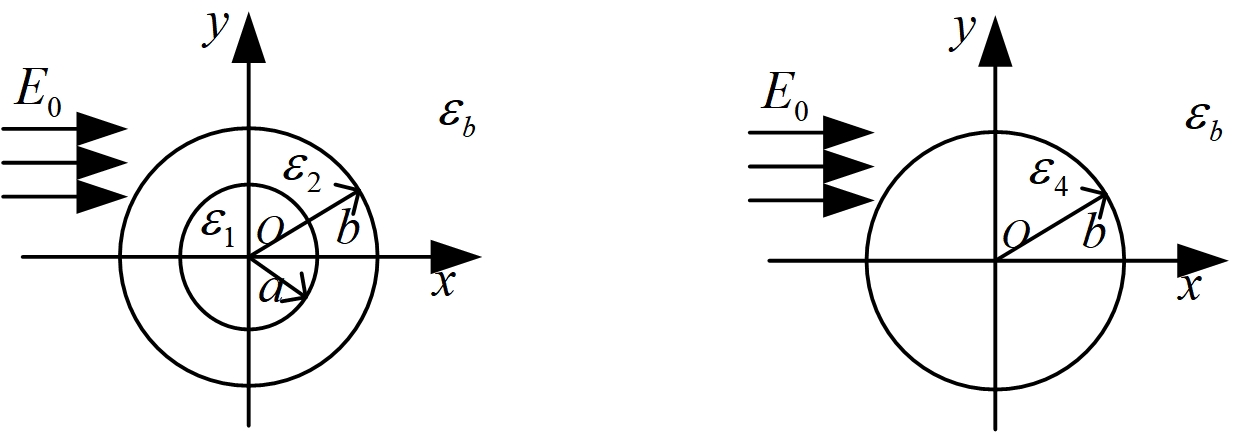

**        对于带有静电幻觉装置的结构，建立柱坐标系，假设各个区域中的电势分布如下：**

  
$$\begin{array}{l}
\phi_1 =\textrm{Arcos}\varphi \\
\phi_2 =\left(\textrm{Br}+\frac{C}{r}\right)\cos \varphi \\
\phi_3 =\left(-E_0 r+\frac{D}{r}\right)\cos \varphi 
\end{array}$$


**        对于幻觉物体模型，电势分布为：**


$$\begin{array}{l}
\phi_4 =A^{\prime } \textrm{rcos}\varphi \\
\phi^{\prime } =\left(\textrm{Mr}+\frac{N}{r}\right)\cos \varphi 
\end{array}$$


**        将各区域的边界条件代入到上式中，可得：**

  
$$\begin{array}{l}
\textrm{Aa}=\textrm{Ba}+\frac{C}{a}\\
\varepsilon_1 A=\varepsilon_2 \left(B-\frac{C}{a^2 }\right)\\
\textrm{Bb}+\frac{C}{b}=-E_0 b+\frac{D}{b}\\
\varepsilon_2 \left(B-\frac{C}{b^2 }\right)=\varepsilon_b \left(-E_0 -\frac{D}{b^2 }\right)\\
\varepsilon_4 A^{\prime } =\varepsilon_b \left(M-\frac{N}{a^2 }\right)\\
A^{\prime } b=\textrm{Mb}+\frac{N}{b}\\
-E_0 r+\frac{D}{r}=\textrm{Mr}+\frac{N}{r}
\end{array}$$


**        假设有一需要幻形处理的是超导材料，即**$\varepsilon_1$**为无穷大，求解上式可得：**


$$\varepsilon_2 \varepsilon_b \left(a^2 +b^2 \right)=\varepsilon_4 \varepsilon_b \left(b^2 -a^2 \right)$$


**        假设超导材料的半径a=0.2，介质柱套外的半径b=0.4，背景材料的介电常数为**$\varepsilon_b =1$**，幻觉物体模型的介电常数为**$\varepsilon_4 =0\ldotp 5$**，计算可知柱套的介电常数为**$\varepsilon_2 =0\ldotp 3$**。**

**       定义参数：**

超导柱半径：

a=0.3;

柱套层半径：

b=0.4;

幻觉物体模型的介电常数：

e4=0.5;

计算可得柱套层的介电常数为：

e2=(b^2-a^2)/(b^2+a^2)*e4

e2 = 0.1400

**        用pdetool仿真：**

- **幻形目标模型的电势分布：**

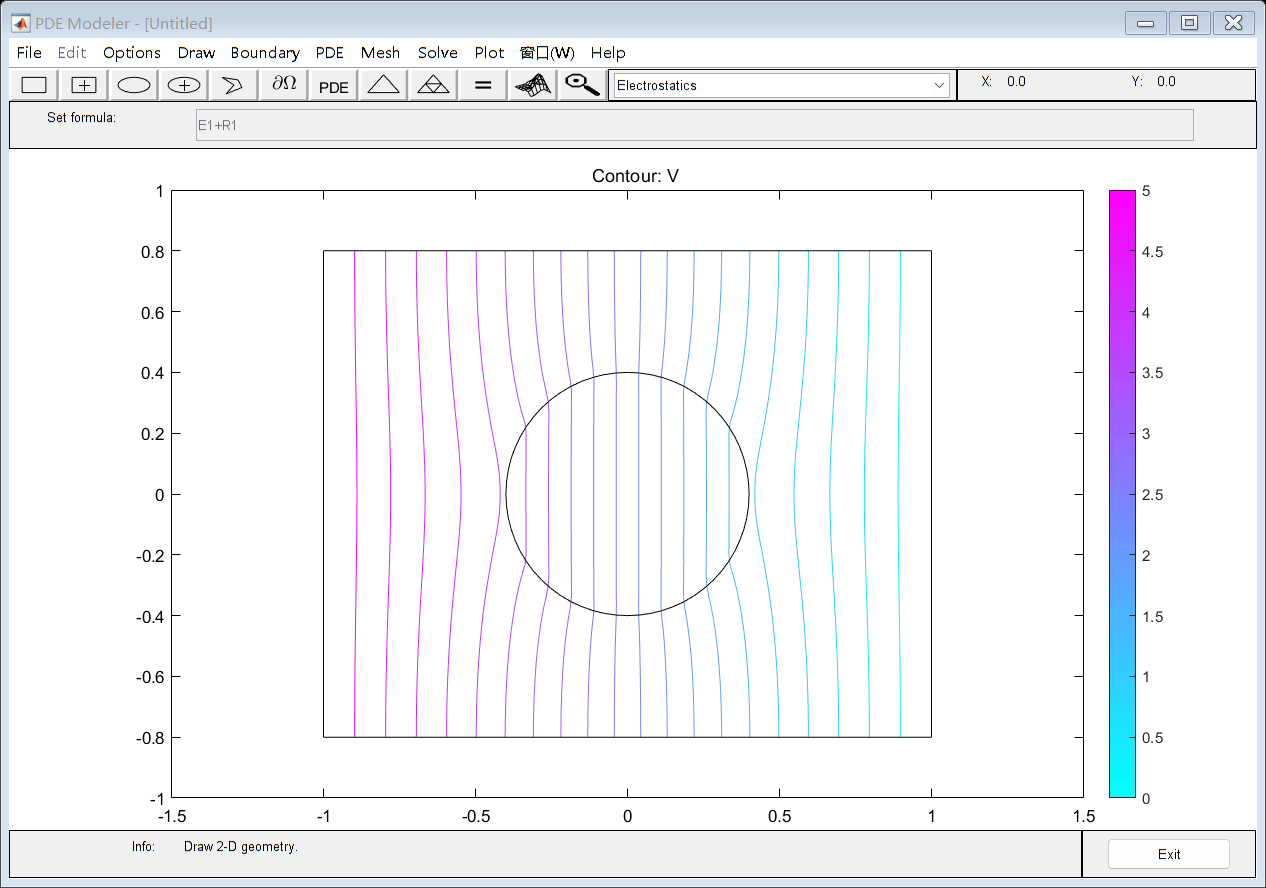

Illusion_Object_Model(a,b,e4)

- **仅有超导柱时的电势分布：**

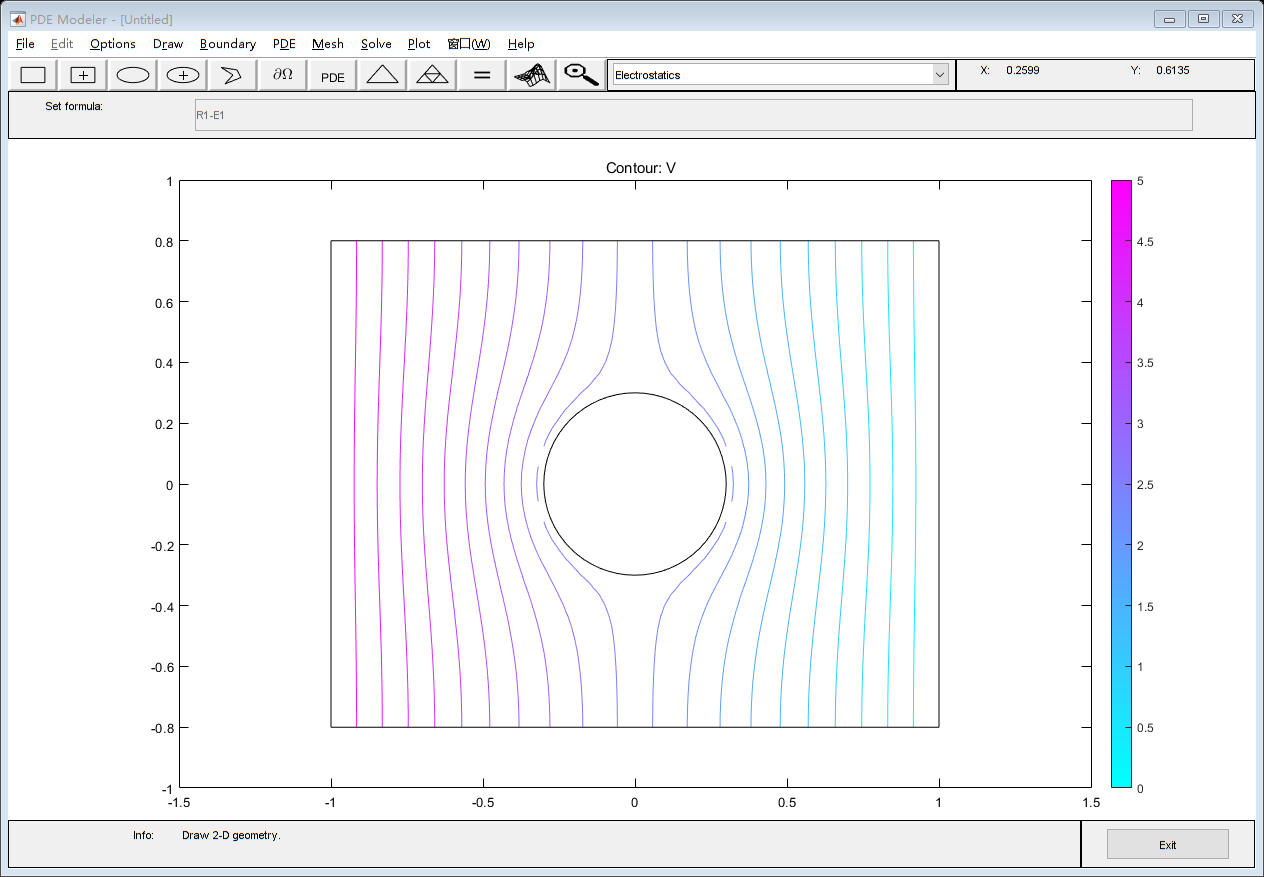

Without_Illusion_Device(a)

- **使用幻形材料包裹金属柱的电势分布：**

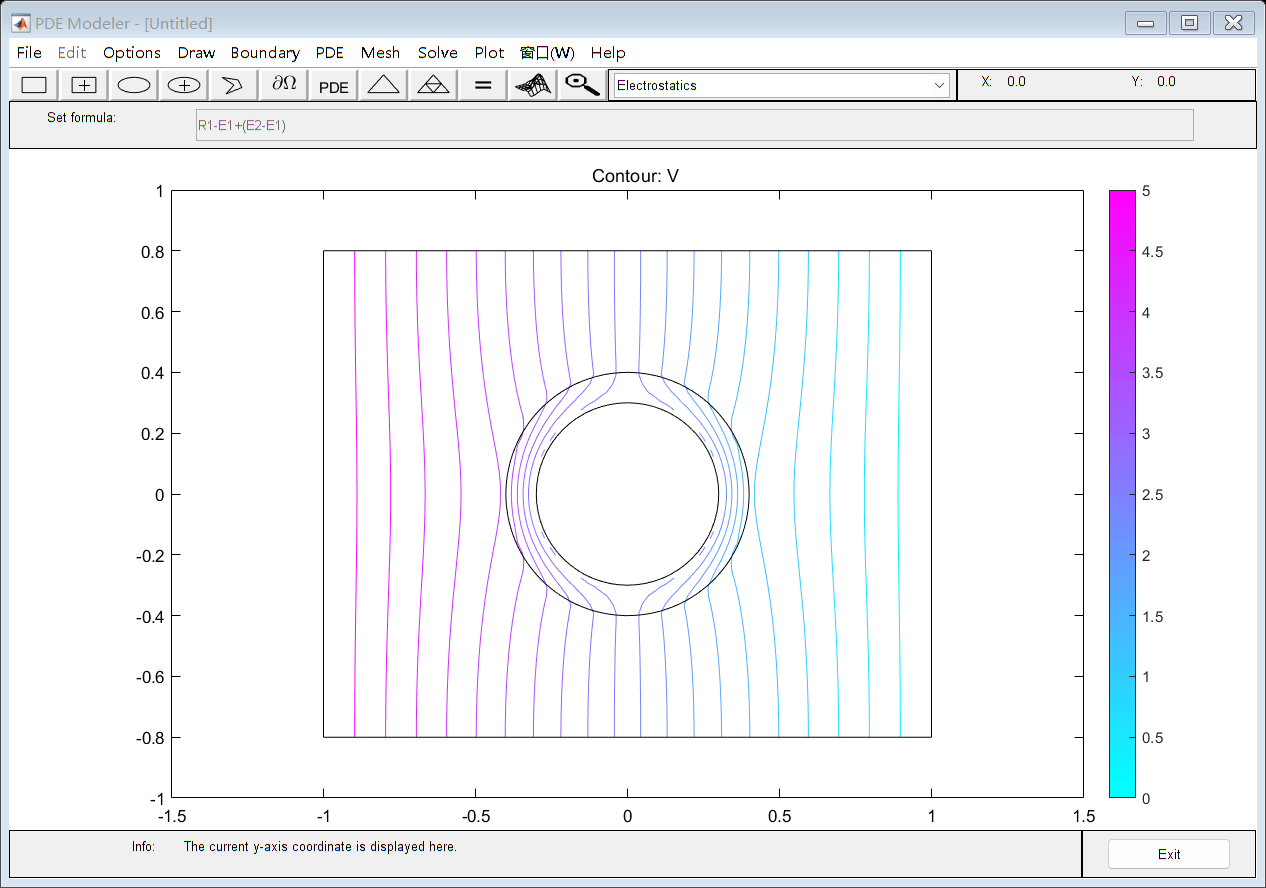

With_Illusion_Device(a,b,e2)

**由上述仿真可以看出，使用幻形材料包裹的金属柱可以具有与其他材料相同的静电场电势分布。**

function  Without_Illusion_Device(a)
    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',5);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5 1 1]);
    set(ax,'XLim',[-1.5 1.5]);
    set(ax,'YLim',[-1 1]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([-1 1 0.80000000000000004 -0.80000000000000004],'R1');
    pdeellip(0,0,a,a,...
    0,'E1');

    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1-E1')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(8,...
    'dir',...
    1,...
    '1',...
    '2.50')
    pdesetbd(7,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(6,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(5,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    '1.0!1',...
    '0.0!0.0',...
    '0!0',...
    '1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    ['1.0!1';...
    '0!0  '])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','6144','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 1 1 1 0 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end

function Illusion_Object_Model(a,b,e4)
    e=['1.0!', num2str(e4)];
    current_density='0!0';
    % Make the string lengths equal
    current_density = [current_density, blanks(length(e) - length(current_density))];

    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',5);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5 1 1]);
    set(ax,'XLim',[-1.5 1.5]);
    set(ax,'YLim',[-1 1]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pdeellip(0,0,b,b,...
    0,'E1');
    pderect([-1 1 0.80000000000000004 -0.80000000000000004],'R1');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','E1+R1')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    e,...
    '0.0!0.0',...
    '0!0',...
    '1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    [e;...
    current_density])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','5904','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 1 1 1 0 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end

function With_Illusion_Device(a,b,e2)
    e=['1.0!', num2str(e2)];
    current_density='0!0';
    % Make the string lengths equal
    current_density = [current_density, blanks(length(e) - length(current_density))];

    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',5);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5 1 1]);
    set(ax,'XLim',[-1.5 1.5]);
    set(ax,'YLim',[-1 1]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([-1 1 0.80000000000000004 -0.80000000000000004],'R1');
    pdeellip(0,0,a,a,...
    0,'E1');
    pdeellip(0,0,b,b,...
    0,'E2');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1-E1+(E2-E1)')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(8,...
    'dir',...
    1,...
    '1',...
    '2.50')
    pdesetbd(7,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(6,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(5,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    e,...
    '0.0!0.0',...
    '0!0',...
    '1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    [e;...
    current_density])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','6144','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 1 1 1 0 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end